clc
clear
vx=20;Cf=100e3;Cr=200e3;m=100;J=2000;lf=1;lr=1;

Open-loop system

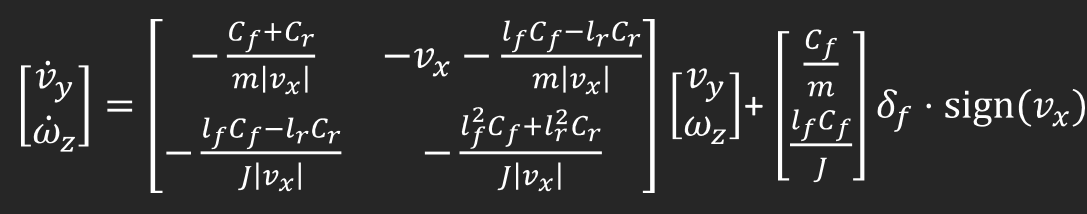

a11 = -(Cf+Cr)/(m*vx);
a12 = -vx - (lf*Cf-lr*Cr)/(m*vx);
a21 = -(lf*Cf-lr*Cr)/(J*vx);
a22 = -(lf^2*Cf+lr^2*Cr)/(J*vx);

A = [a11 a12;a21 a22];
B = [Cf/m; lf*Cf/J]*sign(vx);
C = [1 0;0 1];
D = [0;0];

sys = ss(A,B,C,D);
eig(A)

ans =  -150.5244
   -6.9756


[num, den] = ss2tf(A,B,C,D)

num = 1.0e+04 *

         0    0.1000    0.9000
         0    0.0050    1.0000


den = 1.0e+03 *

    0.0010    0.1575    1.0500


sys_tf = tf(sys)

sys_tf =
 
  From input to output...
          1000 s + 9000
   1:  --------------------
       s^2 + 157.5 s + 1050
 
           50 s + 1e04
   2:  --------------------
       s^2 + 157.5 s + 1050
 
Continuous-time transfer function.




$$G_{\delta-\omega_z} = \frac{50s+10000}{s^2+157.5s+1050}$$


s = tf('s');
% syms s
% C*inv((s*eye(2)-A))*B+D
sys_yawrate = tf(num(2,:), den);
pole(sys_yawrate)

ans =  -150.5244
   -6.9756


zero(sys_yawrate)

ans = -200.0000

amp = @(w)abs((50*w*1i+10000)/(-w^2+157.5*w*1i+1050))

amp = function_handle with value:
    @(w)abs((50*w*1i+10000)/(-w^2+157.5*w*1i+1050))


20*log(amp(16.6296)) % shoulde be 11.2988 when w is 16.6296

ans = 26.0274

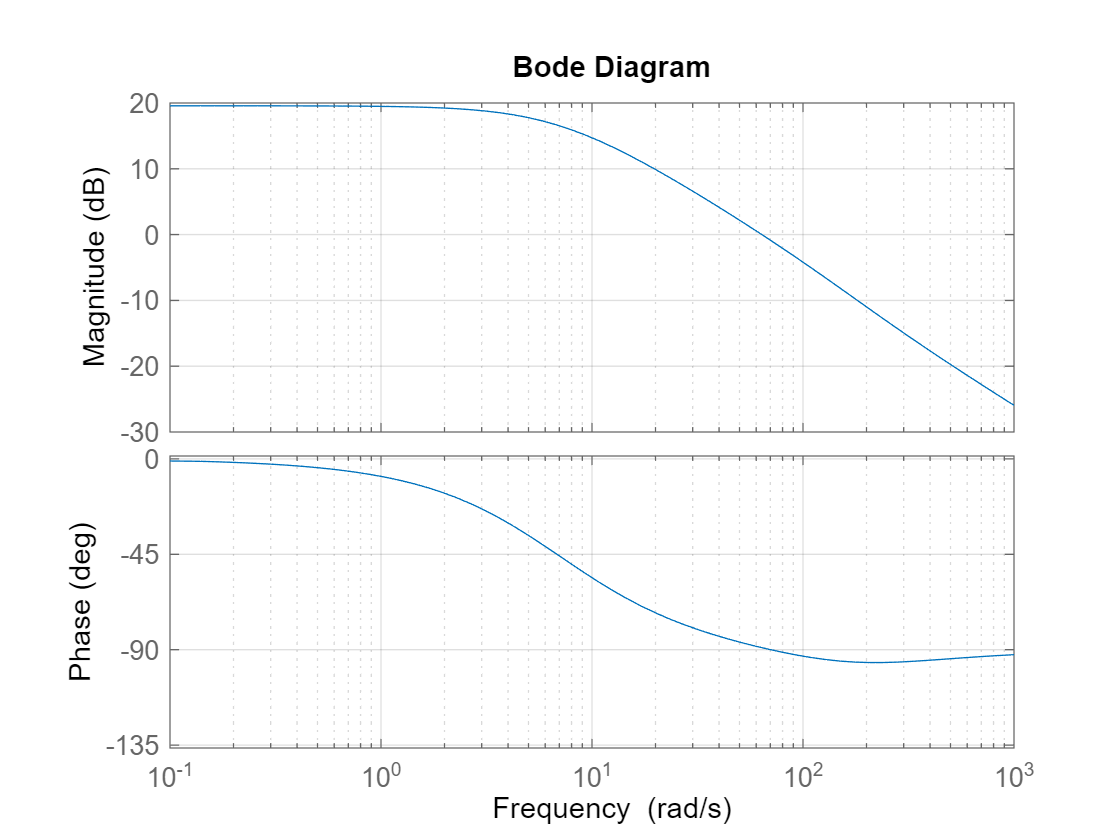

bode(sys_yawrate)
grid on

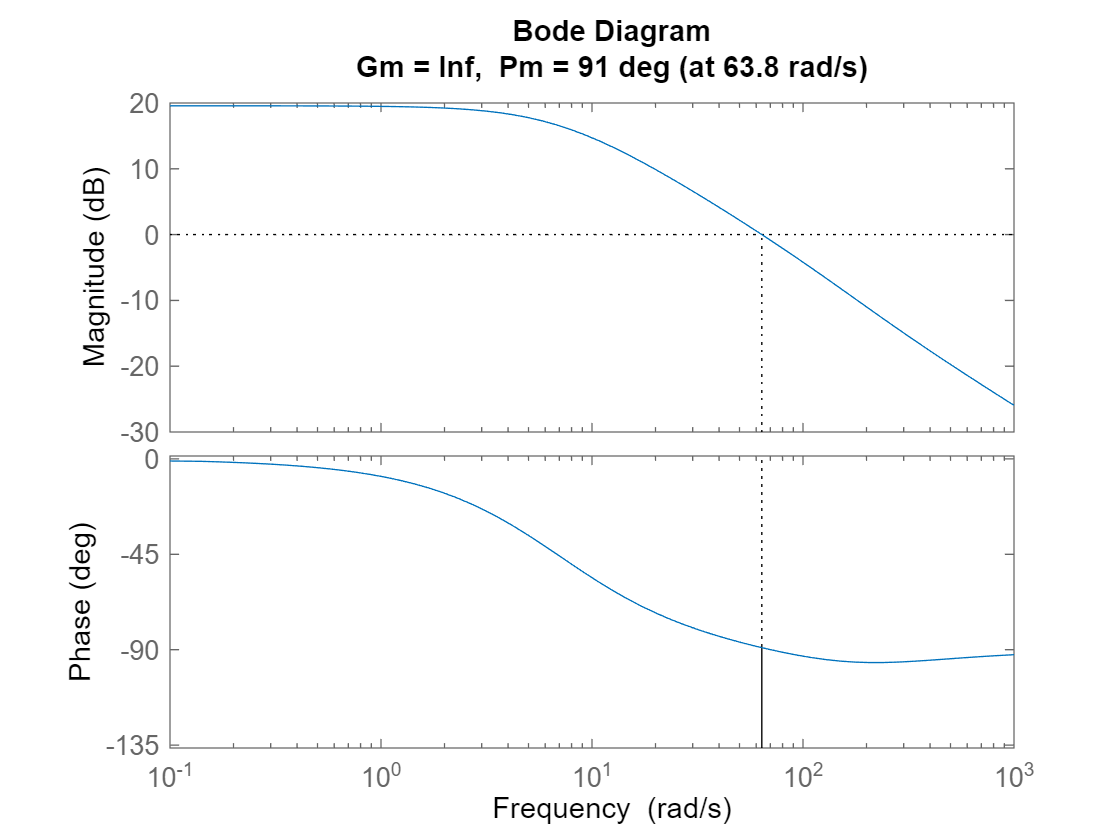

margin(sys_yawrate)

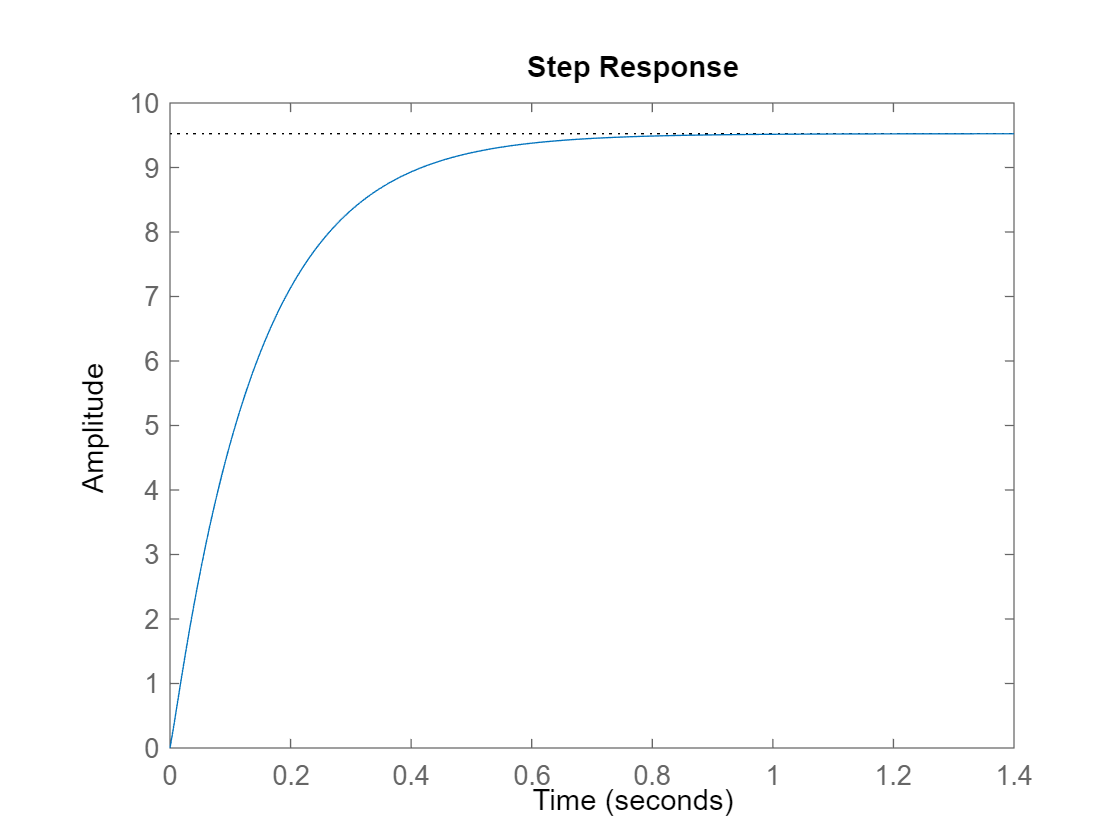

step(sys_yawrate)

## Closed-loop system

yaw angle controller

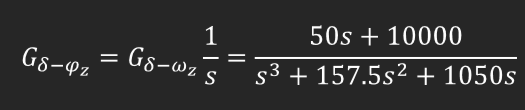

% open-loop transfer funciton
sys_yawAng = 1/s * sys_yawrate;

### Kp =1

Kp = 1;
% closed-loop tf, manual way
cl_yawAng = (Kp*sys_yawAng)/(1+Kp*sys_yawAng)

cl_yawAng =
 
            50 s^4 + 1.787e04 s^3 + 1.627e06 s^2 + 1.05e07 s
  ---------------------------------------------------------------------
  s^6 + 315 s^5 + 2.696e04 s^4 + 3.486e05 s^3 + 2.73e06 s^2 + 1.05e07 s
 
Continuous-time transfer function.



% closed-loop tf, feedback()
cl_yawAng = feedback(Kp*sys_yawAng, 1)

cl_yawAng =
 
            50 s + 1e04
  -------------------------------
  s^3 + 157.5 s^2 + 1100 s + 1e04
 
Continuous-time transfer function.



pole(cl_yawAng)

ans = 1.0e+02 *

  -1.5064 + 0.0000i
  -0.0343 + 0.0739i
  -0.0343 - 0.0739i


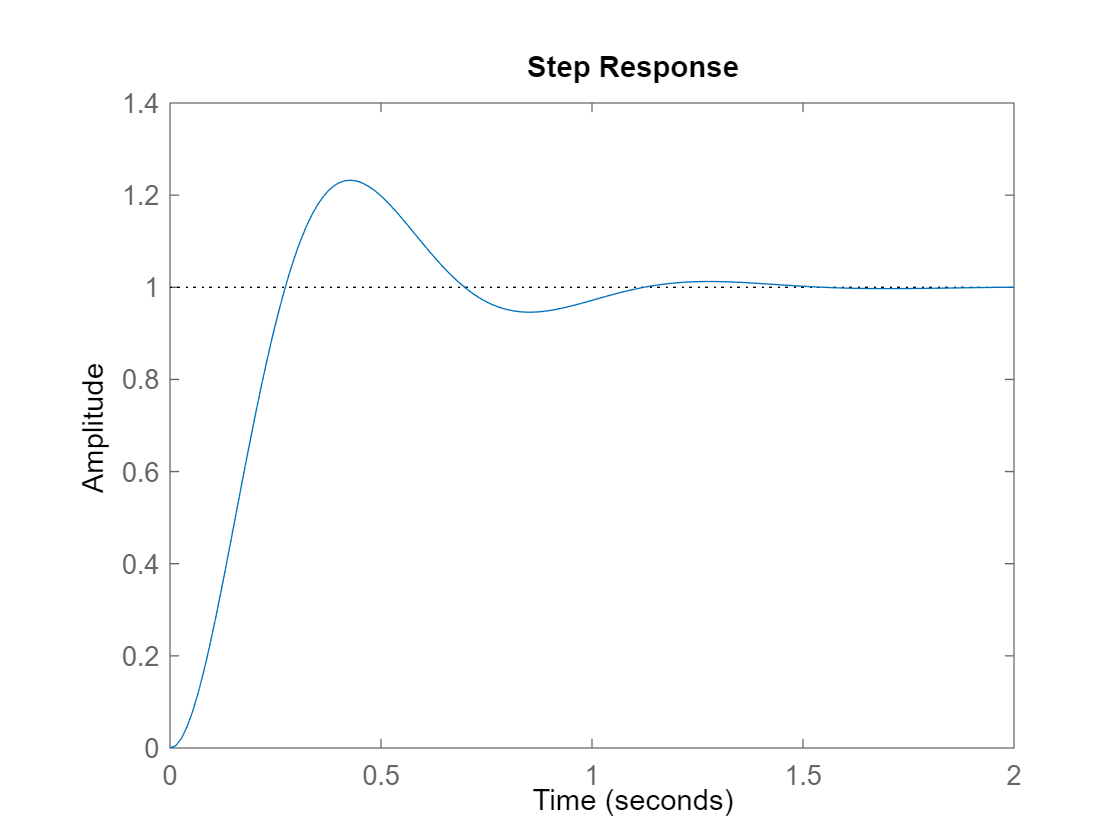

step(cl_yawAng)

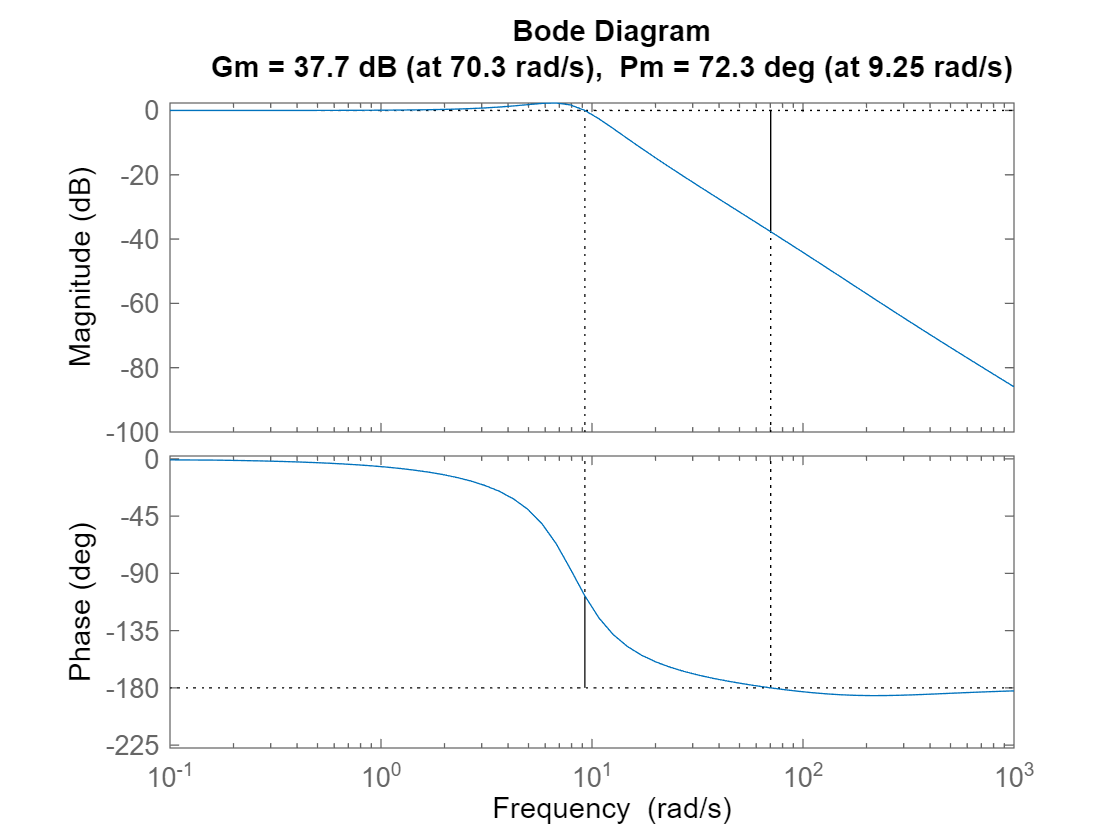

margin(cl_yawAng)

### Kp = 10

Kp=10;
cl_yawAng = feedback(Kp*sys_yawAng, 1)

cl_yawAng =
 
           500 s + 1e05
  -------------------------------
  s^3 + 157.5 s^2 + 1550 s + 1e05
 
Continuous-time transfer function.



pole(cl_yawAng)

ans = 1.0e+02 *

  -1.5163 + 0.0000i
  -0.0294 + 0.2551i
  -0.0294 - 0.2551i


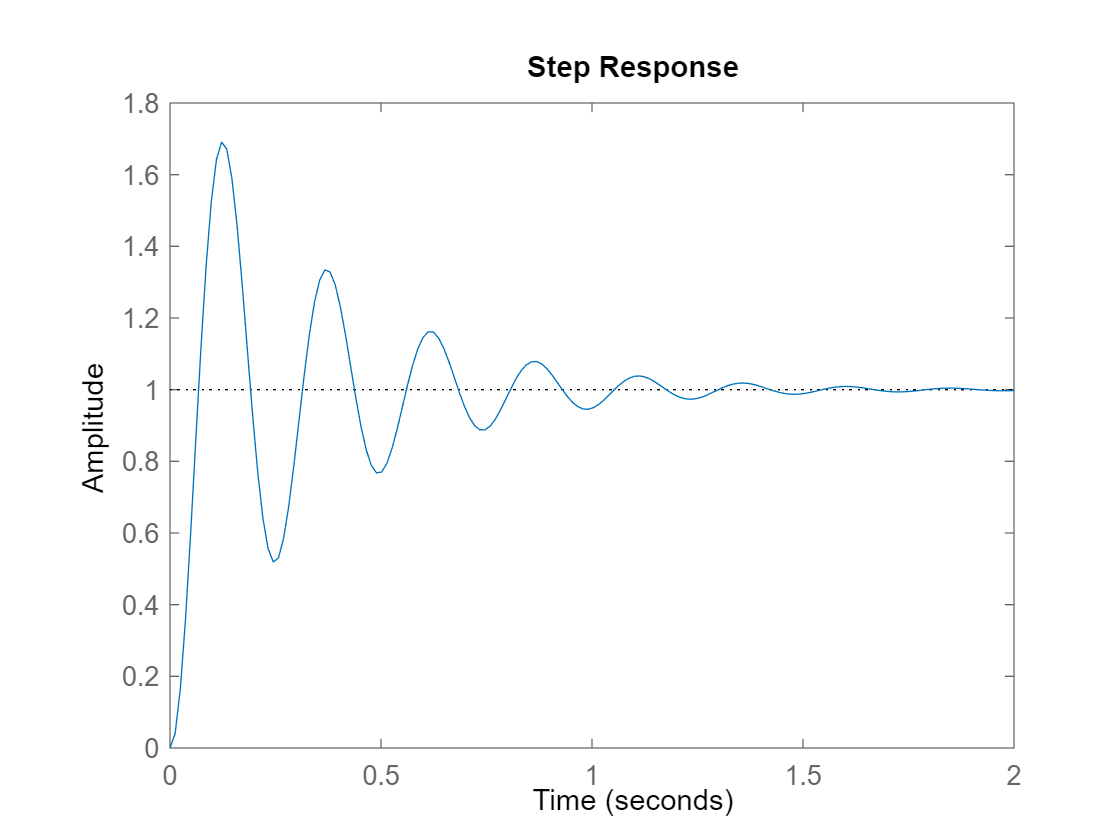

step(cl_yawAng)

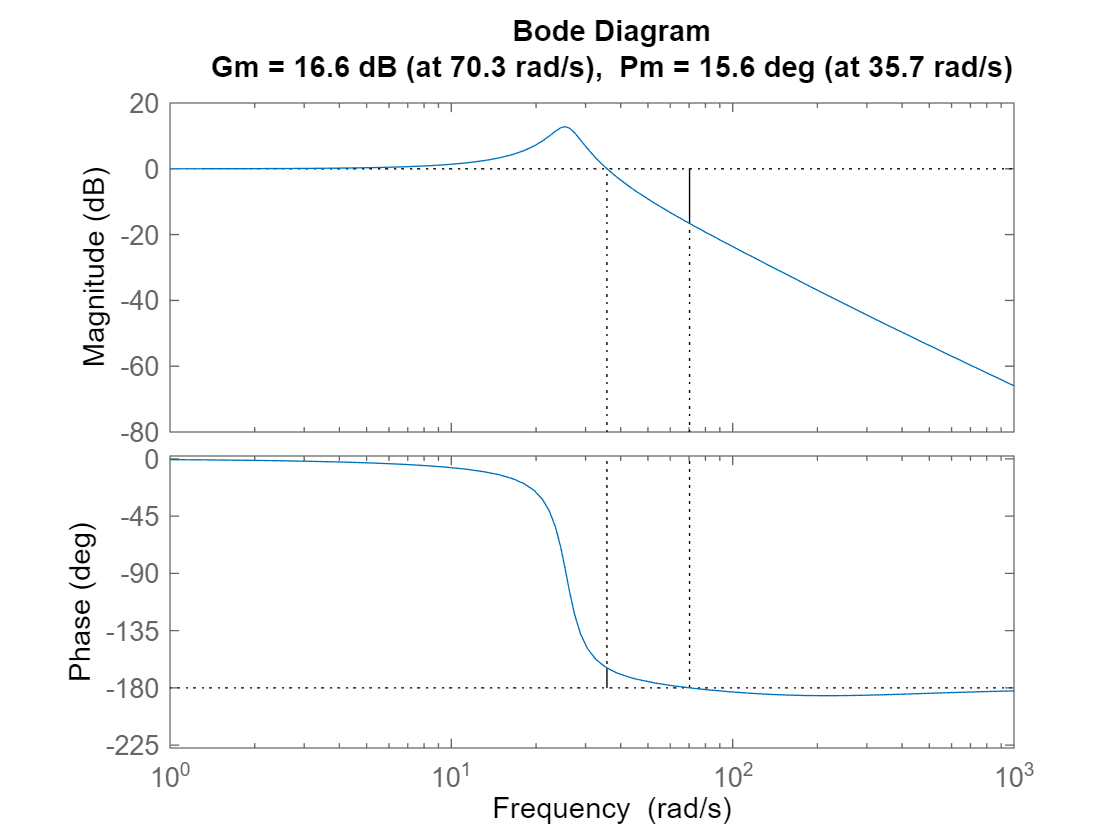

margin(cl_yawAng)

### Kp =100

Kp = 100;
cl_yawAng = feedback(Kp*sys_yawAng, 1)

cl_yawAng =
 
           5000 s + 1e06
  -------------------------------
  s^3 + 157.5 s^2 + 6050 s + 1e06
 
Continuous-time transfer function.



pole(cl_yawAng)

ans = 1.0e+02 *

  -1.5900 + 0.0000i
   0.0075 + 0.7930i
   0.0075 - 0.7930i


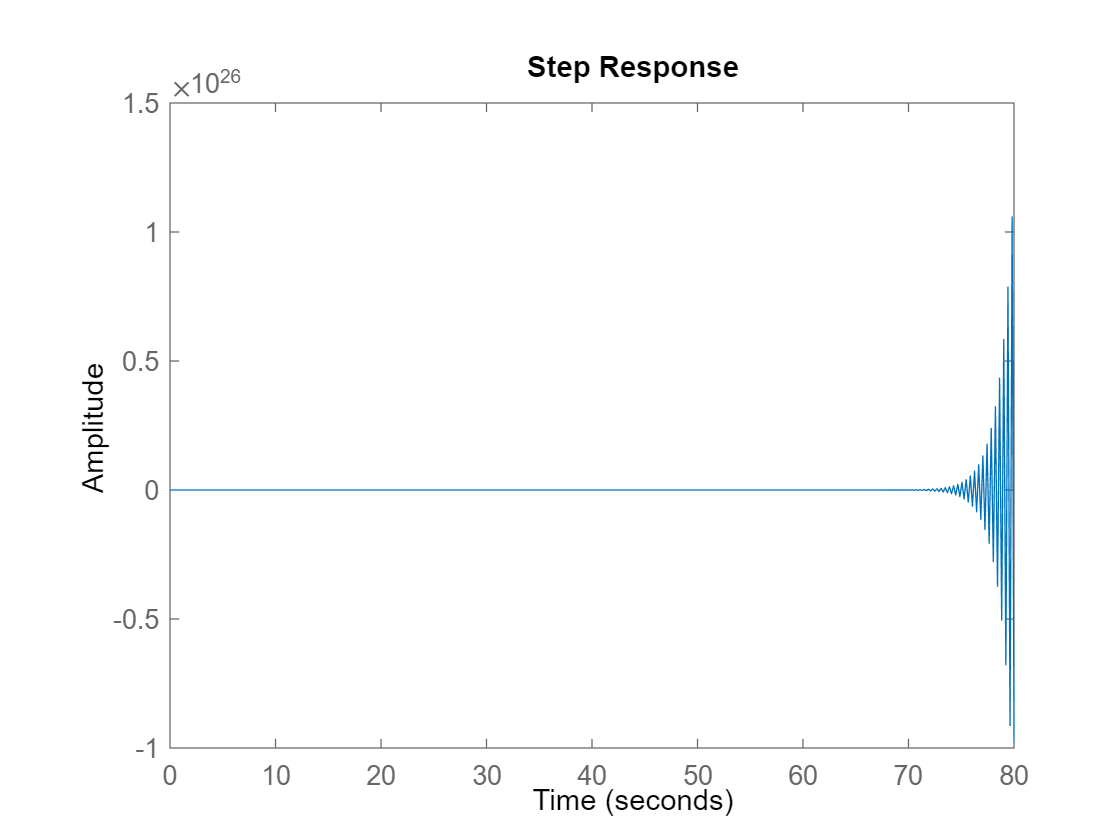

step(cl_yawAng)

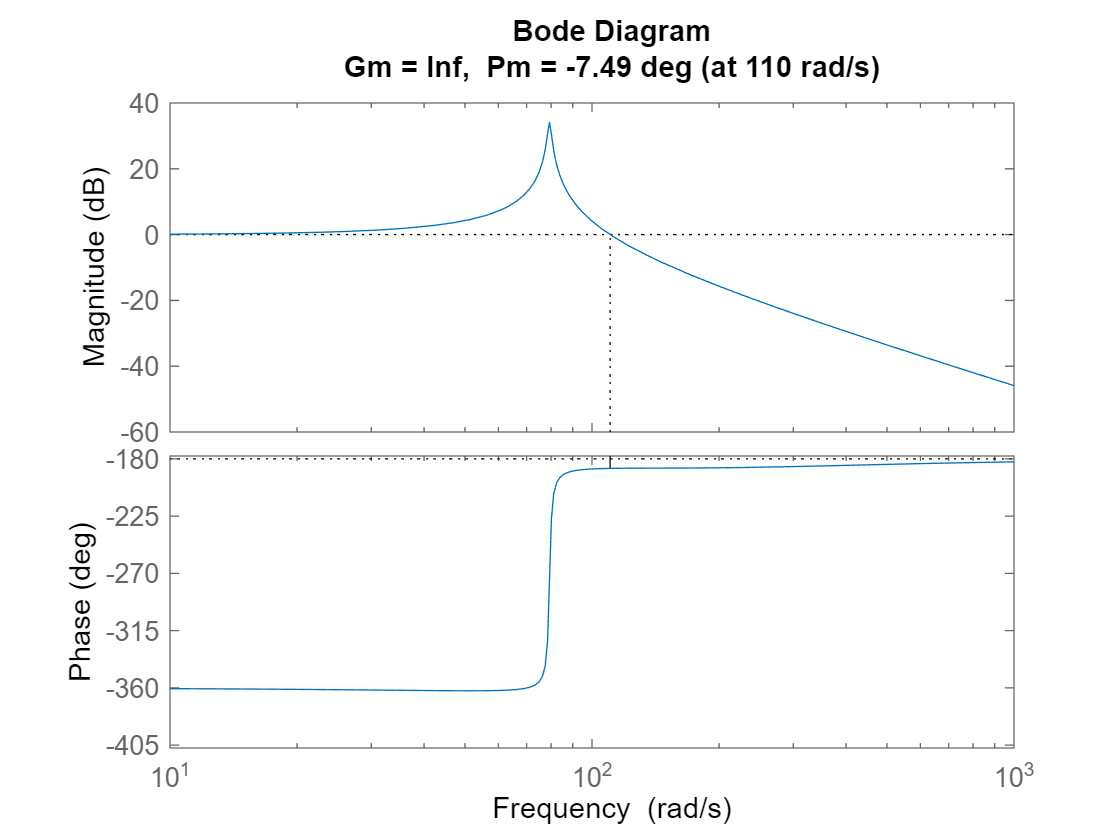

margin(cl_yawAng)